%select teh top 200 columns and run the analysis on them

% figure('Position',[100, 100, 2400, 1200]);
plotidx=0;
allsubj={7349, 7356, 7361, 7375, 7376,...
         7383, 7402, 7403, 7404,...
         7405, 7408, 7414, 7415,...
         7425, 7426, 7433, 7434,...
         7435, 7443, 7444, 7445,...
         7448, 7449, 7452, 7453,...
         7454, 7455, 7456, 7457,...
         7468, 7469, 7482, 7484, 7485}; %34subj 7349 output was too big-->not safed and need to rerun, and 7356 has no good orientation was not run at all.32 is visualized now

% remlstatsubj={7349,7361,  7375,7383,  7402,  7403,  7404};
subplotsize=[8 4];
% disp('This is the distribution of the indiviudal T value(across columns) for the three contrast')
for subj=allsubj%remlstatsubj%allsubj%{7414,7482,7484,7485}
    roipath='C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\';
    columnartsfile=[roipath num2str(subj{:}) '\functionalmasks\interimdata_rwls.mat']; %this is the S1 sampled matrices
    if exist(columnartsfile,"file")
%         disp(subj)
        disp([num2str(subj{:}) ' subject columnar info r'])
        plotidx=plotidx+1;
        %set the contrasts value in BK_firstlvlanalysis to the one which we
        %are interested
        [stat,columndistribution,layerwisestat]=BK_layer_sampling_pain_study_pipeline(subj,'glmestimate','S1');
        allsubjid(plotidx)=subj{:};
        allsubjlayer{plotidx}=layerwisestat;
%         allsubjlayer_contrastinglm{plotidx}=layerwisestat;

        allsubjcoldistr{plotidx}=columndistribution;
        allsubjstat{plotidx}=stat;
%         subplot(subplotsize(1), subplotsize(2), plotidx);
%         hcogn=histogram(stat.T(:,:,1),'BinLimits',[-5,5],'FaceColor', 'blue');
%         hold on
%         hpain=histogram(stat.T(:,:,2),'BinLimits',[-5,5],'FaceColor', 'red');
%         hconj=histogram(stat.T(:,:,3),'BinLimits',[-5,5],'FaceColor', 'green');
%         xline(1,'-','LineWidth', 1.5,'Color', 'blue');
%         xline(0,'-','LineWidth', 1.5,'Color', 'red');
%         title(num2str(subj{:}))
%         if plotidx==1
%             legend('Cognitive act (Blue)', 'Pain act (Red)','Conjuction act (Blue)','t>1', 'Location', 'northwestoutside');
%         end
%         
%         hold off
    else
        disp([num2str(subj{:}) ' subject has  no sampled cluster'])
    end

end

7349 subject has  no sampled cluster
7356 subject has  no sampled cluster


7361 subject columnar info r


Time for one subject to process:Elapsed time is 2.717270 seconds.


7375 subject columnar info r


Time for one subject to process:Elapsed time is 2.883902 seconds.


7376 subject columnar info r


Time for one subject to process:Elapsed time is 2.564874 seconds.


7383 subject columnar info r


Time for one subject to process:Elapsed time is 2.483699 seconds.


7402 subject columnar info r


Time for one subject to process:Elapsed time is 4.512406 seconds.


7403 subject columnar info r


Time for one subject to process:Elapsed time is 2.810341 seconds.


7404 subject columnar info r


Time for one subject to process:Elapsed time is 2.236055 seconds.


7405 subject columnar info r


Time for one subject to process:Elapsed time is 2.088744 seconds.


7408 subject columnar info r


Time for one subject to process:Elapsed time is 3.281127 seconds.


7414 subject columnar info r


Time for one subject to process:Elapsed time is 2.492236 seconds.


7415 subject columnar info r


Time for one subject to process:Elapsed time is 2.846566 seconds.


7425 subject columnar info r


Time for one subject to process:Elapsed time is 2.459955 seconds.


7426 subject columnar info r


Time for one subject to process:Elapsed time is 2.666296 seconds.


7433 subject columnar info r


Time for one subject to process:Elapsed time is 2.339628 seconds.


7434 subject columnar info r


Time for one subject to process:Elapsed time is 2.421138 seconds.


7435 subject columnar info r


Time for one subject to process:Elapsed time is 2.156737 seconds.


7443 subject columnar info r


Time for one subject to process:Elapsed time is 2.234534 seconds.


7444 subject columnar info r


Time for one subject to process:Elapsed time is 3.277708 seconds.


7445 subject columnar info r


Time for one subject to process:Elapsed time is 2.572079 seconds.


7448 subject columnar info r


Time for one subject to process:Elapsed time is 2.402201 seconds.


7449 subject columnar info r


Time for one subject to process:Elapsed time is 2.635528 seconds.


7452 subject columnar info r


Time for one subject to process:Elapsed time is 2.341666 seconds.


7453 subject columnar info r


Time for one subject to process:Elapsed time is 2.598630 seconds.


7454 subject columnar info r


Time for one subject to process:Elapsed time is 2.638007 seconds.


7455 subject columnar info r


Time for one subject to process:Elapsed time is 2.354656 seconds.


7456 subject columnar info r


Time for one subject to process:Elapsed time is 2.253935 seconds.


7457 subject columnar info r


Time for one subject to process:Elapsed time is 2.364067 seconds.


7468 subject columnar info r


Time for one subject to process:Elapsed time is 2.135256 seconds.


7469 subject columnar info r


Time for one subject to process:Elapsed time is 2.438978 seconds.


7482 subject columnar info r


Time for one subject to process:Elapsed time is 2.576520 seconds.


7484 subject columnar info r


Time for one subject to process:Elapsed time is 2.370181 seconds.


7485 subject columnar info r


Time for one subject to process:Elapsed time is 2.176006 seconds.



%when all the conditions are esimated separately, we can visualize the
%indiviudal ßs as a function of layer
%visualize hte ß distribution as a function of layers
%     {'pain_high_cogn_high_pain'   }
%     {'pain_high_cogn_low_pain'    }
%     {'pain_low_cogn_high_pain'    }
%     {'pain_low_cogn_low_pain'     }
HCHP=[];
LCHP=[];
HCLP=[];
LCLP=[];
for subj=1:length(allsubjlayer)
    HCHP(subj,:)=allsubjlayer{subj}.beta(:,:,1);
    HCLP(subj,:)=allsubjlayer{subj}.beta(:,:,2);

    LCHP(subj,:)=allsubjlayer{subj}.beta(:,:,3);
    LCLP(subj,:)=allsubjlayer{subj}.beta(:,:,4);
%     allsubjlayerresp(subj,:)=mean(squeeze(allsubjlayer{subj}.beta(:,:,:,1)),2)';    
end
bottomup_beta=(HCHP+LCHP)-(HCLP+LCLP);
topdown_beta=(LCHP+LCLP)-(HCHP+HCLP);


%save the output as a matrix, so I can do the plotting/stat in R

pathtooutput='C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\layerdata\';
% alldata={HCHP, HCLP,LCHP,LCLP};
% alldatanm={'HCHP', 'HCLP','LCHP','LCLP'};
% for conditionid=1:4
%     writematrix(alldata{conditionid},[ pathtooutput 'S1_' alldatanm{conditionid} '.csv'])
% end
% writematrix(allsubjid',[pathtooutput 'S1_subjid.csv'])
ncond=4;
nsubj=length(allsubjid);
s1_layeractivation=array2table([HCHP;HCLP;LCHP;LCLP],'VariableNames',strcat("layer",string(1:20)));
s1_layeractivation.cognition=[repmat("high",nsubj,1);...
              repmat("high",nsubj,1);...
              repmat("low",nsubj,1);...
              repmat("low",nsubj,1)];
s1_layeractivation.pain=[repmat("high",nsubj,1);...
              repmat("low",nsubj,1);...
              repmat("high",nsubj,1);...
              repmat("low",nsubj,1)];
s1_layeractivation.subjid=string(repmat(allsubjid',ncond,1));
writetable(s1_layeractivation,[ pathtooutput 'S1_layervalues_percond.csv'])

bottomup_beta=(HCHP+LCHP)-(HCLP+LCLP);
topdown_beta=(LCHP+LCLP)-(HCHP+HCLP);
nproc=2;
s1=array2table([bottomup_beta;topdown_beta],'VariableNames',strcat("layer",string(1:20)));
s1.process=[repmat("bottomup",nsubj,1);repmat("topdown",nsubj,1)];
s1.side=[repmat("right",nsubj*nproc,1)];
s1.subjid=string(repmat(allsubjid',nproc,1));

writetable(s1,[ pathtooutput 'S1_layervalues.csv'])



%define different contrast:
effofcognlcminusHc_ofhighpain_cognsuppression=LCHP-HCHP;

interactioneffect_positivelikebehavior=(LCHP-HCHP)-(LCLP-HCLP);

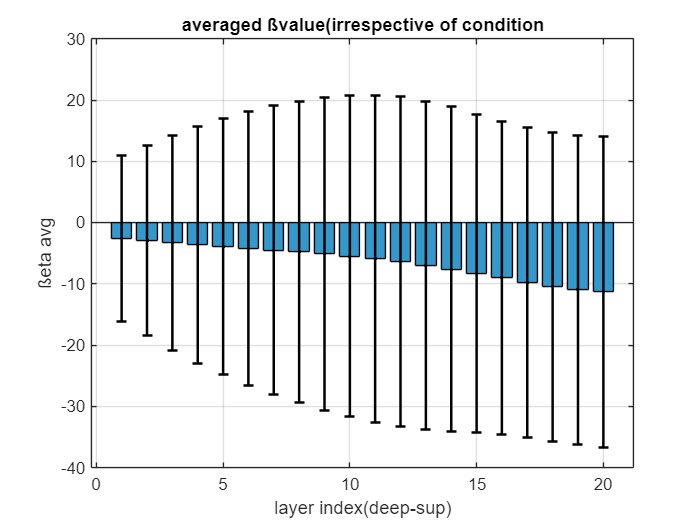

figure;
alldata=[HCHP; HCLP;LCHP;LCLP];
columnMeans = mean(alldata, 1); % Mean of each column
columnStdDevs = std(alldata, 0, 1); % Standard deviation of each column

% Create the bar plot
% subplot(2,2,plotidx)
bar(columnMeans, 'FaceColor', [0.2 0.6 0.8]); % Bar plot with custom color
hold on;

% Add error bars
errorbar(1:length(columnMeans), columnMeans, columnStdDevs, ...
    'k.', 'LineWidth', 1.5); % Error bars in black

% Customize the plot
xlabel('layer index(deep-sup)');
ylabel('ßeta avg');
title('averaged ßvalue(irrespective of condition');

grid on;

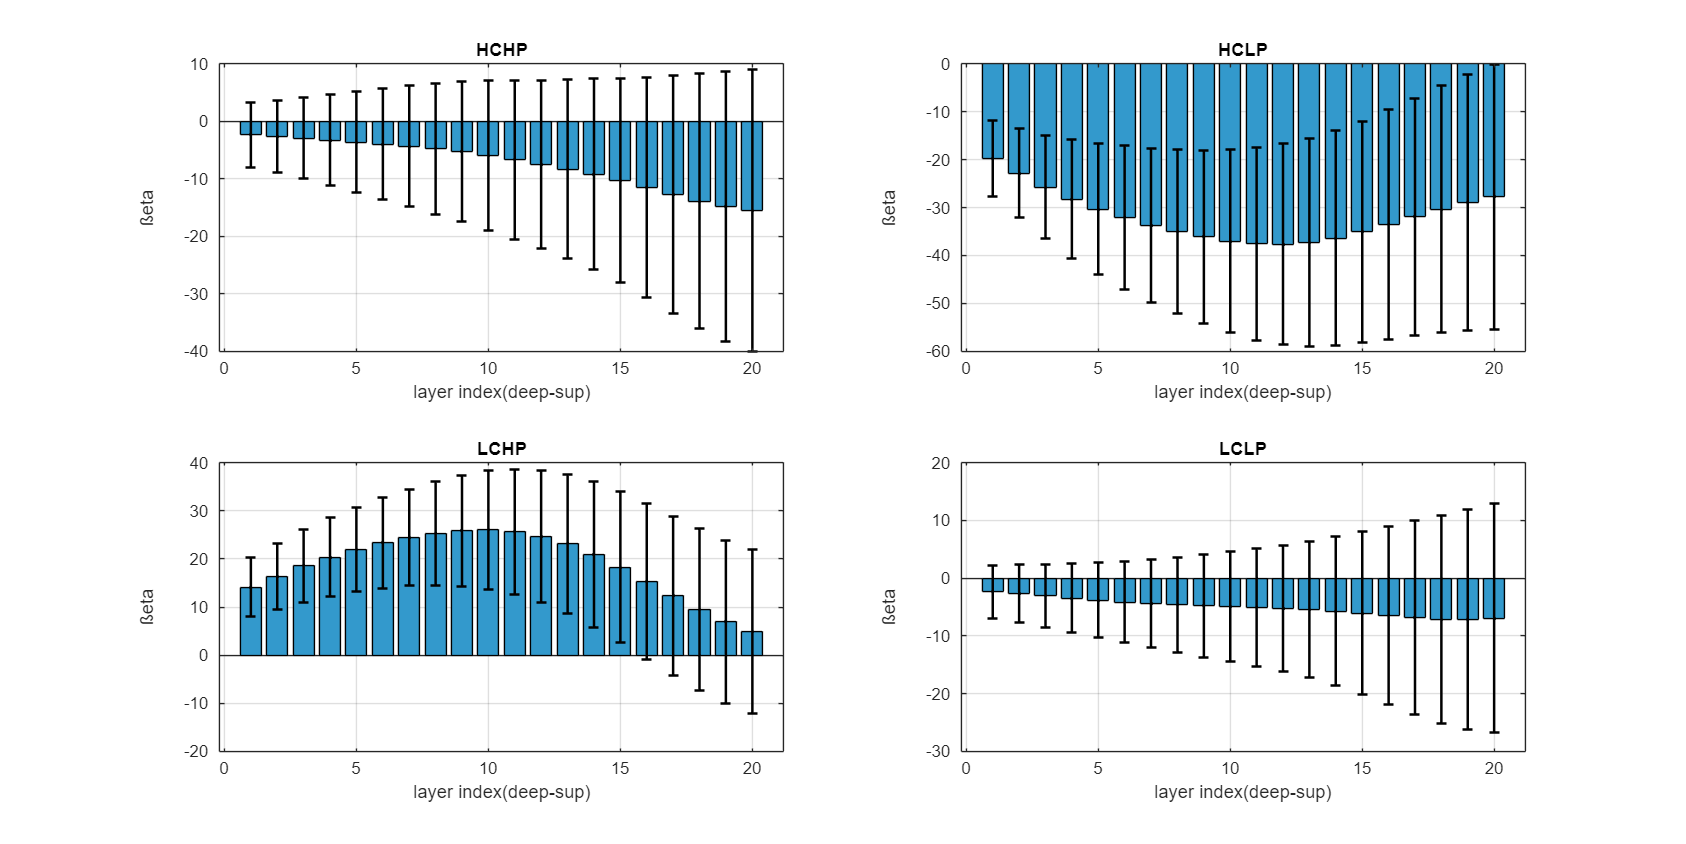

figure('Position',[100, 100, 2400, 1200]);
plotidx=0;
alldata={HCHP, HCLP,LCHP,LCLP};
alldatanm={'HCHP', 'HCLP','LCHP','LCLP'};
for dataidx=1:4
%     allsubjlayerresp(subj,:)=mean(squeeze(allsubjlayer{subj}.beta(:,:,:)),2)';
%     allsubjlayerresp_T(subj,:)=mean(squeeze(allsubjlayer{subj}.T(:,:,:)),2)';
    plotidx=plotidx+1;
    data=alldata{dataidx};
% Example matrix of size 10x20
%     data = allsubjlayerresp; % Random data for demonstration
    
    % Calculate column-wise mean and standard deviation
    columnMeans = mean(data, 1); % Mean of each column
    columnStdDevs = std(data, 0, 1); % Standard deviation of each column
    
    % Create the bar plot
    subplot(2,2,plotidx)
    bar(columnMeans, 'FaceColor', [0.2 0.6 0.8]); % Bar plot with custom color
    hold on;
    
    % Add error bars
    errorbar(1:length(columnMeans), columnMeans, columnStdDevs, ...
        'k.', 'LineWidth', 1.5); % Error bars in black
    
    % Customize the plot
    xlabel('layer index(deep-sup)');
    ylabel('ßeta');
    title(alldatanm{dataidx});
    grid on;
    hold off;
end

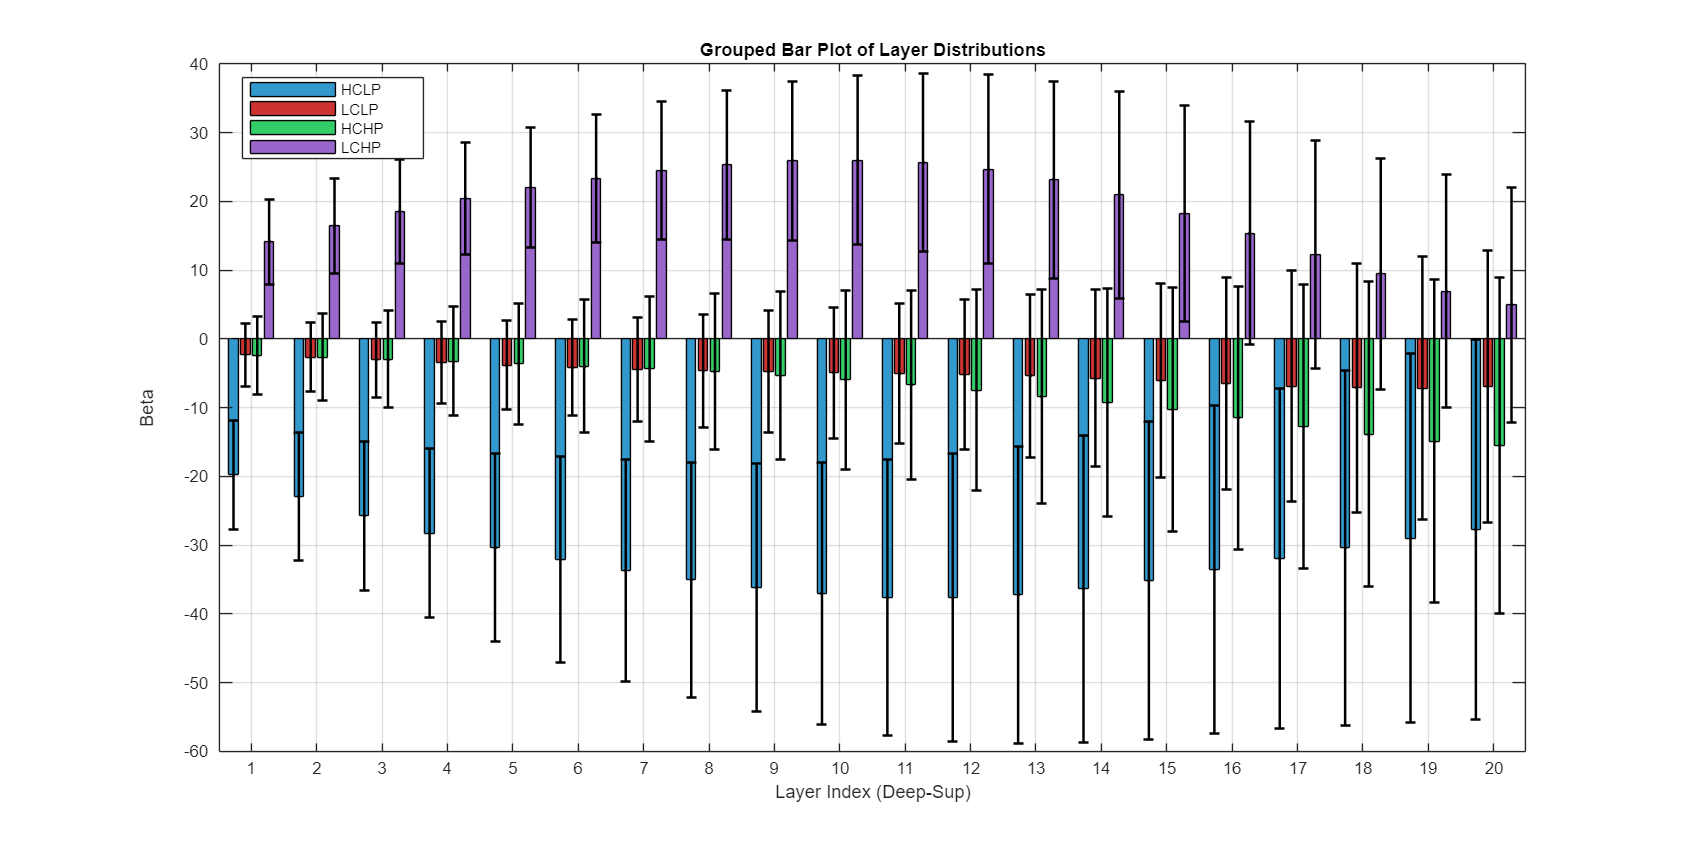

% Example data
% Replace these with your actual data matrices of size Nx20

% Group all data and names
figure('Position',[100, 100, 2400, 1200]);
alldata = {HCLP, LCLP,HCHP,LCHP};
alldatanm = {'HCLP', 'LCLP','HCHP','LCHP'};

% Calculate column-wise means and standard deviations for each dataset
numDatasets = length(alldata);
numColumns = size(alldata{1}, 2); % Assuming all datasets have the same column size
columnMeans = zeros(numDatasets, numColumns);
columnStdDevs = zeros(numDatasets, numColumns);

for i = 1:numDatasets
    columnMeans(i, :) = mean(alldata{i}, 1); % Mean for dataset i
    columnStdDevs(i, :) = std(alldata{i}, 0, 1); % Standard deviation for dataset i
end

% Plot grouped bar plot
% figure('Position', [100, 100, 1200, 600]);
barHandles = bar(1:numColumns, columnMeans', 'grouped'); % Transpose for grouped bars

% Set different colors for each dataset
colors = [0.2, 0.6, 0.8; % Blue
          0.8, 0.2, 0.2; % Red
          0.2, 0.8, 0.4; % Green
          0.6, 0.4, 0.8]; % Purple
for i = 1:numDatasets
    barHandles(i).FaceColor = 'flat';
    barHandles(i).CData = repmat(colors(i, :), numColumns, 1); % Apply color
end

% Add error bars
hold on;
groupWidth = min(0.8, numDatasets / (numDatasets + 1.5)); % Adjust width for grouped bars
for i = 1:numDatasets
    % Calculate x positions for error bars
    x = (1:numColumns) - groupWidth / 2 + (2 * i - 1) * groupWidth / (2 * numDatasets);
    errorbar(x, columnMeans(i, :), columnStdDevs(i, :), 'k.', 'LineWidth', 1.5);
end
hold off;

% Customize the plot
xlabel('Layer Index (Deep-Sup)');
ylabel('Beta');
title('Grouped Bar Plot of Layer Distributions');
xticks(1:numColumns);
xticklabels(arrayfun(@num2str, 1:numColumns, 'UniformOutput', false));
legend(alldatanm, 'Location', 'northwest');
grid on;

%visualize the two main effect


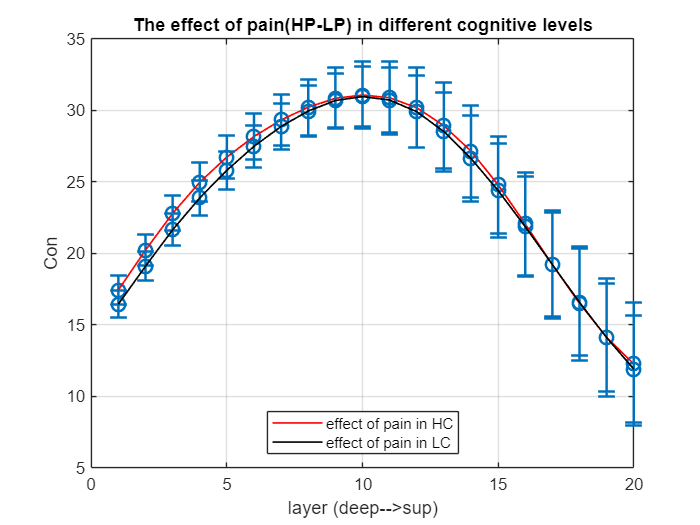

%visualize the effect of pain on different levels of cogntive load

painon_HC=HCHP-HCLP; %effectof pain on high congition
painon_LC=LCHP-LCLP; %effectof pain on low congition
figure;
alldata={painon_HC, painon_LC};
for dataidx=1:2
    % Calculate column-wise mean and standard error
    data=alldata{dataidx};
    columnMeans = mean(data, 1); % Mean of each column
    columnStdErrors = std(data, 0, 1) ./ sqrt(size(data, 1)); % Standard error
    
    % Create the scatter plot
    
    errorbar(1:20, columnMeans, columnStdErrors, ...
        'o', 'LineWidth', 1.5, 'MarkerSize', 8, 'Color', [0 0.4470 0.7410], 'CapSize', 10);
    hold on;
    
    % Connect the points with a line
    if dataidx==1
        lineHandle1=plot(1:20, columnMeans, '-r', 'LineWidth', 1);
    else
        lineHandle2=plot(1:20, columnMeans, '-k', 'LineWidth', 1);
    end
    
    % Customize the plot
    xlabel('layer (deep-->sup)');
    ylabel('Con');
    title('The effect of pain(HP-LP) in different cognitive levels');

    grid on;
end

legend([lineHandle1,lineHandle2], ...
        {'effect of pain in HC', ...
        'effect of pain in LC'}, ...
        'Location', 'south');
hold off;

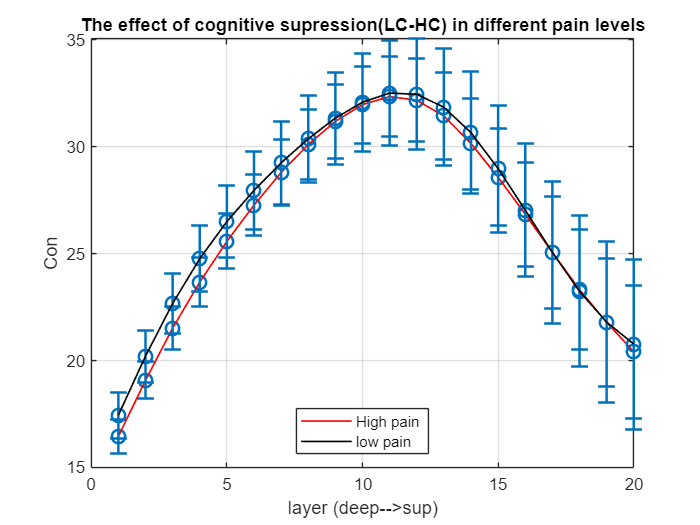

%visualize the effect of cognition in different pain levels

cogneff_onHP=LCHP-HCHP;
cogneff_onLP=LCLP-HCLP;
figure;
alldata={cogneff_onHP, cogneff_onLP};
for dataidx=1:2
    % Calculate column-wise mean and standard error
    data=alldata{dataidx};
    columnMeans = mean(data, 1); % Mean of each column
    columnStdErrors = std(data, 0, 1) ./ sqrt(size(data, 1)); % Standard error
    
    % Create the scatter plot
    
    errorbar(1:20, columnMeans, columnStdErrors, ...
        'o', 'LineWidth', 1.5, 'MarkerSize', 8, 'Color', [0 0.4470 0.7410], 'CapSize', 10);
    hold on;
    
    % Connect the points with a line
    if dataidx==1
        lineHandle1=plot(1:20, columnMeans, '-r', 'LineWidth', 1);
    else
        lineHandle2=plot(1:20, columnMeans, '-k', 'LineWidth', 1);
    end
    
    % Customize the plot
    xlabel('layer (deep-->sup)');
    ylabel('Con');
    title('The effect of cognitive supression(LC-HC) in different pain levels');

    grid on;
end

legend([lineHandle1,lineHandle2], ...
        {'High pain', ...
        'low pain'}, ...
        'Location', 'south');
hold off;


%interacitoneffect
interactioneffect_positivelikebehavior=(LCHP-HCHP)-(LCLP-HCLP);

interactioneffect_positiveUNlikebehavior=(LCLP-HCLP)-(LCHP-HCHP);

data=interactioneffect_positiveUNlikebehavior; 
% Calculate column-wise mean and standard deviation
columnMeans = mean(data, 1); % Mean of each column
% columnStdDevs = std(data, 0, 1); % Standard deviation of each column
columnStdErrors = std(data, 0, 1) ./ sqrt(size(data, 1)); % Standard error

% Create the bar plot

figure;
lineHandle1 = plot(1:20, columnMeans, '-r', 'LineWidth', 1);
% bar(columnMeans, 'FaceColor', [0.2 0.6 0.8]); % Bar plot with custom color
hold on;

% Add error bars
errorbar(1:length(columnMeans), columnMeans, columnStdErrors, ...
    'k.', 'LineWidth', 1.5); % Error bars in black

% Customize the plot
xlabel('laminar depth(deep->sup)');
ylabel('con');
title('Layer dependency of interaction effect (positive means the effect of cognition is higher in the low pain level) ');
grid on;
legend([lineHandle1], ...
        {'(LCHP-HCHP)-(LCLP-HCLP)'}, ...
        'Location', 'south');
disp('this is a reversed pattern as in the behavior pattern, that is the effect of cognition is bigger in the low pain condition(that was reversed in the behavior: cognition has higher effect on the high pain condition)')

this is a reversed pattern as in the behavior pattern, that is the effect of cognition is bigger in the low pain condition(that was reversed in the behavior: cognition has higher effect on the high pain condition)


disp("However, the interaction has no layer dependency here (overlappin SE)")

However, the interaction has no layer dependency here (overlappin SE)


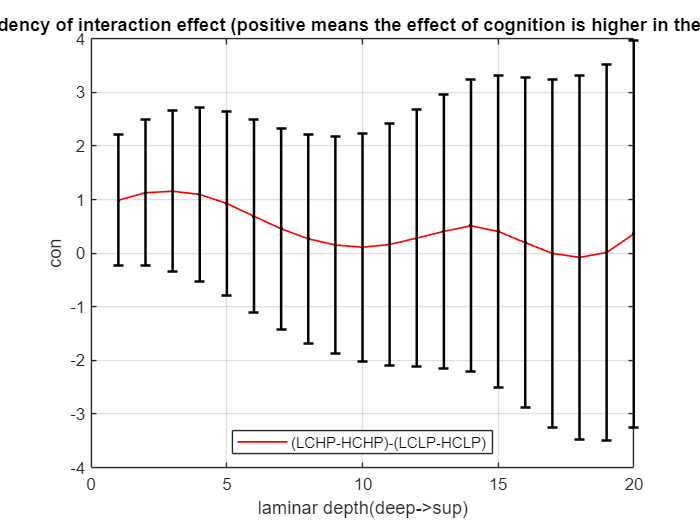

hold off;

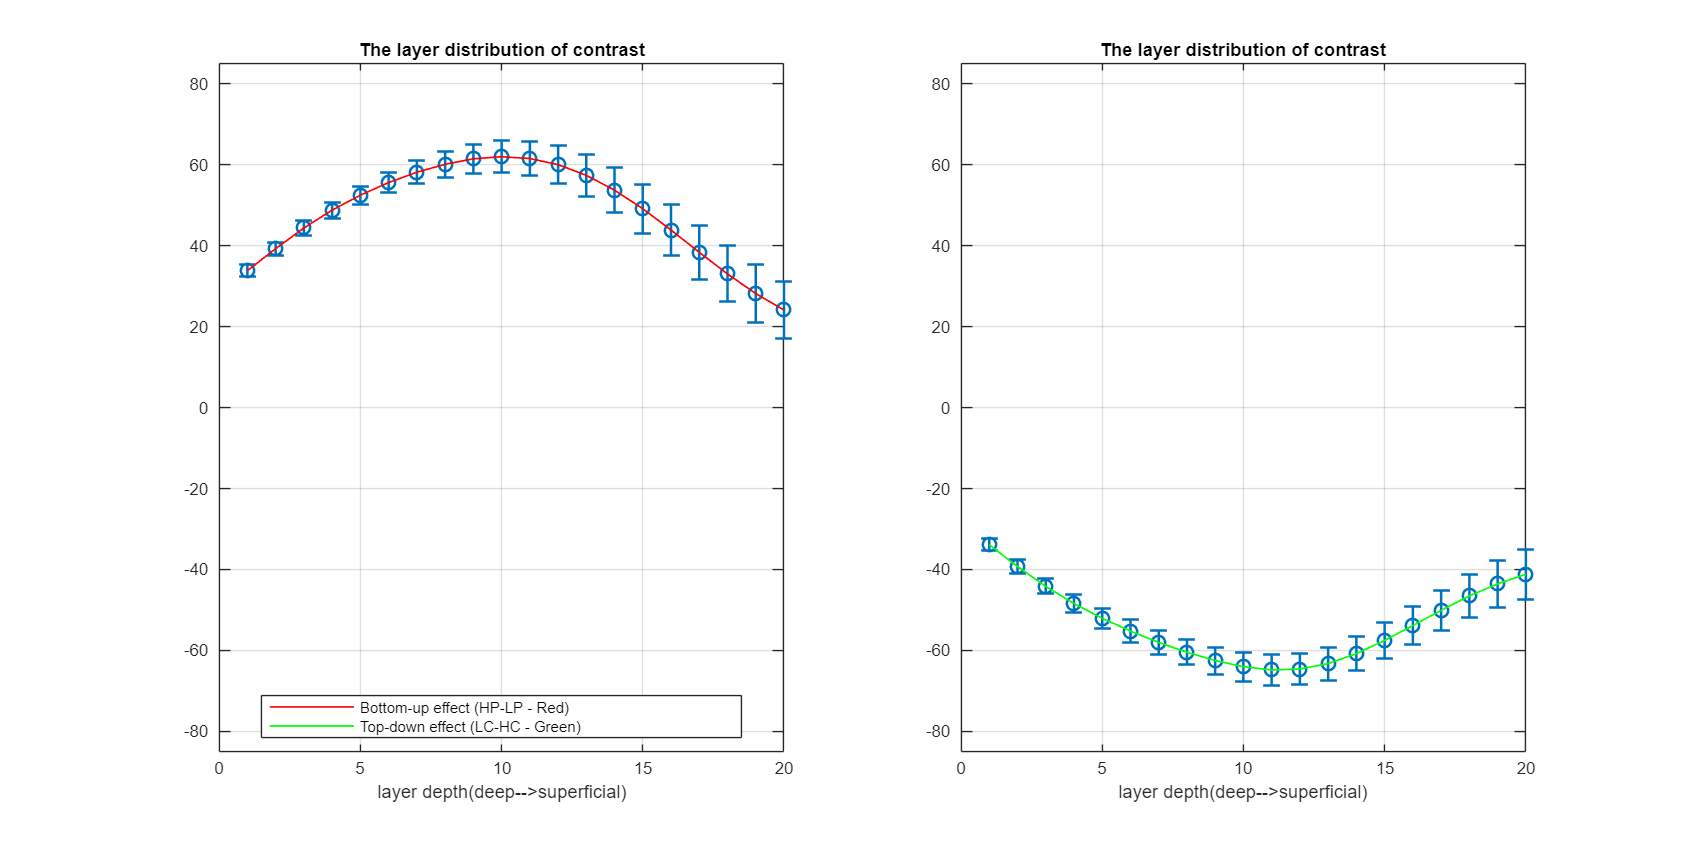

figure('Position',[100, 100, 2400, 1200]);

bottomup_beta=(HCHP+LCHP)-(HCLP+LCLP);
topdown_beta=(LCHP+LCLP)-(HCHP+HCLP);
% topdown_beta2=(HCHP+HCLP)-(LCHP+LCLP);

alldata_beta={bottomup_beta, -topdown_beta};
% alldata_t={bottomup_t,topdown_t};
% for stattype=1:2
for dataidx=1:2
    % Calculate column-wise mean and standard error
    data=alldata_beta{dataidx};

    titlenm='The layer distribution of contrast';
    ylabltxt='con';
    columnMeans = mean(data, 1); % Mean of each column
    columnStdErrors = std(data, 0, 1) ./ sqrt(size(data, 1)); % Standard error
%         subplot(1,2,stattype)
    subplot(1,2,dataidx)
    % Create the scatter plot
%         legend('Bottom-up affect (main eff of pain - Red)','Top-down (main effect of cognition - Blue)', 'Location', 'south');

    errorbar(1:20, columnMeans, columnStdErrors, ...
        'o', 'LineWidth', 1.5, 'MarkerSize', 8, 'Color', [0 0.4470 0.7410], 'CapSize', 10);
    hold on;
    
    % Connect the points with a line
    if dataidx==1
        lineHandle1 = plot(1:20, columnMeans, '-r', 'LineWidth', 1);
    elseif dataidx==2
        lineHandle2 = plot(1:20, columnMeans, '-g', 'LineWidth', 1);
%     elseif dataidx==3
%         lineHandle3 = plot(1:20, columnMeans, '-y', 'LineWidth', 1);
    end

    % Customize the plot
    xlabel('layer depth(deep-->superficial)');
%     ylabel(ylabltxt);
%     ylim([10 85])
    ylim([-85 85])
    % Add legend only for the lines
    
%     label()
    title(titlenm);
    grid on;
    
end
legend([lineHandle1, lineHandle2], ...
    {'Bottom-up effect (HP-LP - Red)', ...
    'Top-down effect (LC-HC - Green)'}, ...
    'Location', 'south');
hold off;

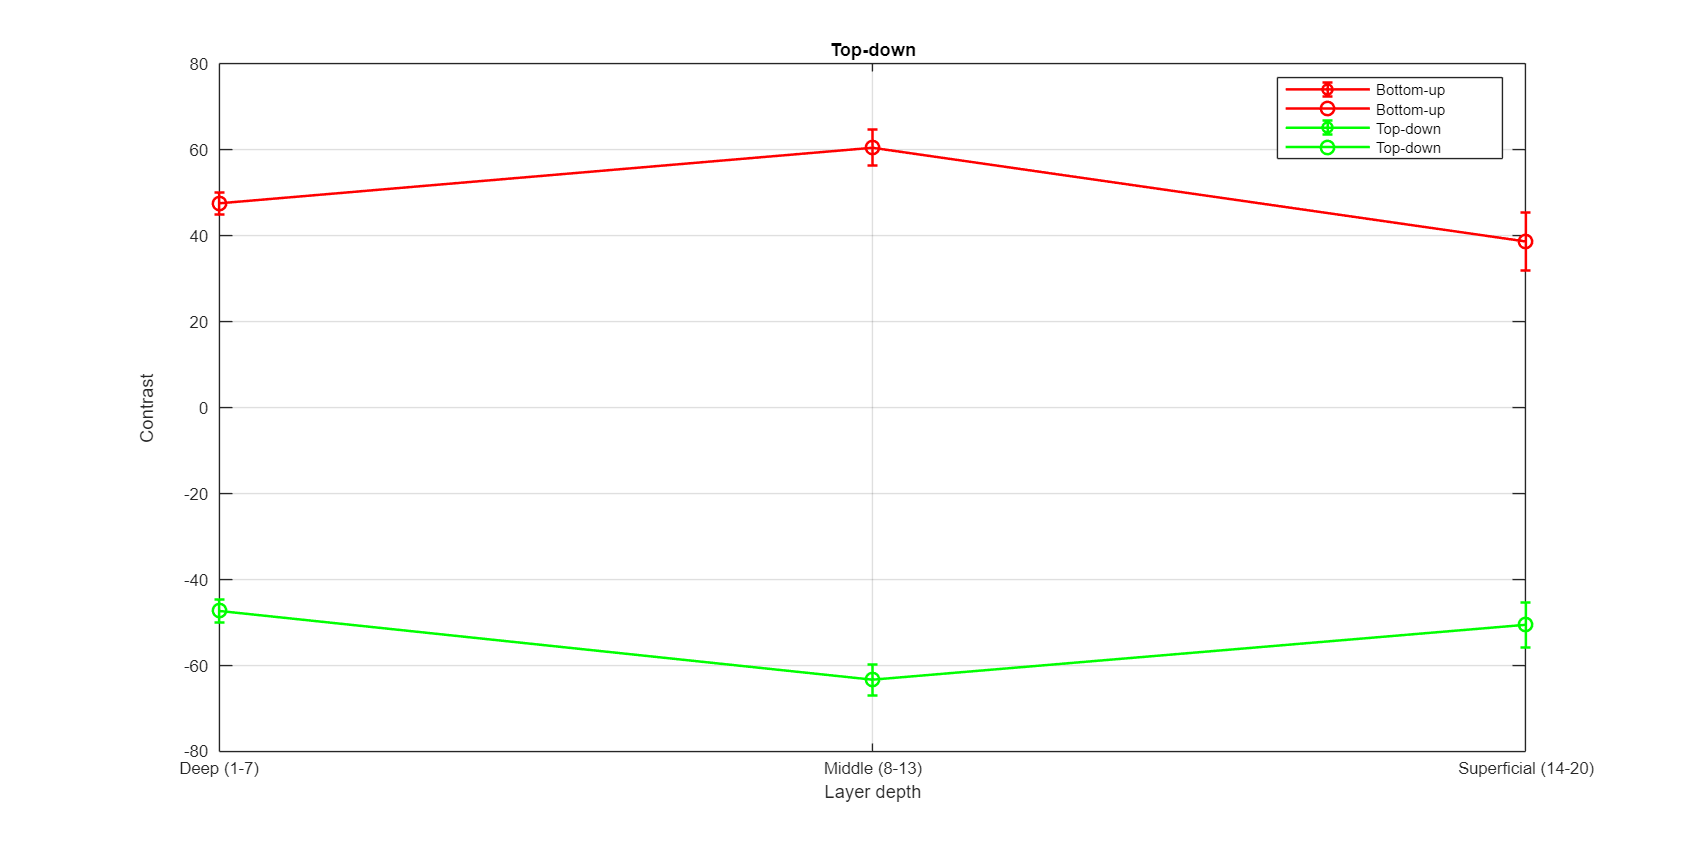

% Create a separate figure
figure('Position', [100, 100, 2400, 1200]);

% Define bin ranges
binRanges = {[1:7], [8:13], [14:20]};
binLabels = {'Deep (1-7)', 'Middle (8-13)', 'Superficial (14-20)'};

% Initialize data for binned means
binnedMeans = zeros(2, length(binRanges)); % Two rows for bottom-up and top-down
binnedSEs = zeros(2, length(binRanges));   % Two rows for standard errors
ploidx=0;
alldata_beta={bottomup_beta, -topdown_beta};
binnedMeans_subj={};
for dataidx = 1:2
    ploidx=ploidx+1;
    data = alldata_beta{dataidx};
    if dataidx == 1
        
        legendLabel = 'Bottom-up';
        lineColor = 'r';
    else
        
        legendLabel = 'Top-down';
        lineColor = 'g';
    end
%     subplot(1,2,ploidx)
    % Compute the means for each bin
    for binIdx = 1:length(binRanges)
        binCols = binRanges{binIdx}; % Get the column indices for the bin
        binData = data(:, binCols);  % Extract data for the bin
        binnedMeans_subj{dataidx}(:, binIdx)=mean(data(:, binCols), 2);
        binnedMeans(dataidx, binIdx) = mean(mean(data(:, binCols), 1)); % Mean over bin
        binnedSEs(dataidx, binIdx) = std(binData(:)) / sqrt(length(binData)); % Standard error
    
    end
    errorbar(1:length(binRanges), binnedMeans(dataidx, :), binnedSEs(dataidx, :), '-o', ...
        'LineWidth', 1.5, 'MarkerSize', 8, 'Color', lineColor, 'DisplayName', legendLabel);
    hold on
    % Plot the binned means
    plot(1:length(binRanges), binnedMeans(dataidx, :), '-o', 'LineWidth', 1.5, ...
        'MarkerSize', 8, 'Color', lineColor, 'DisplayName', legendLabel);
    hold on

    xticks(1:length(binRanges));
    xticklabels(binLabels);
    xlabel('Layer depth');
    ylabel('Contrast');
    
    grid on;
    title(legendLabel);
    legend('Location', 'northeast');
%     ylim([40 80])
    ylim([-80 80])
end

% Customize the plot


hold off;


% this is the effect of pain(bottom up) and effect of cogntition (top-down)
% in the layer profile when the contrast was calculated within the GLM (s o
% individual T values are also provided.

for subj=1:length(allsubjlayer)
    topdown_beta(subj,:)=allsubjlayer_contrastinglm{subj}.beta(:,1,1);
    bottomup_beta(subj,:)=allsubjlayer_contrastinglm{subj}.beta(:,1,2);
    

    
    topdown_t(subj,:)=allsubjlayer{subj}.T(:,1,1);
    bottomup_t(subj,:)=allsubjlayer{subj}.T(:,1,2);

%     HC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,1);
% 
%     LC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,2);
%     allsubjlayerresp(subj,:)=mean(squeeze(allsubjlayer{subj}.beta(:,:,:,1)),2)';    
end

Undefined variable allsubjlayer_contrastinglm.

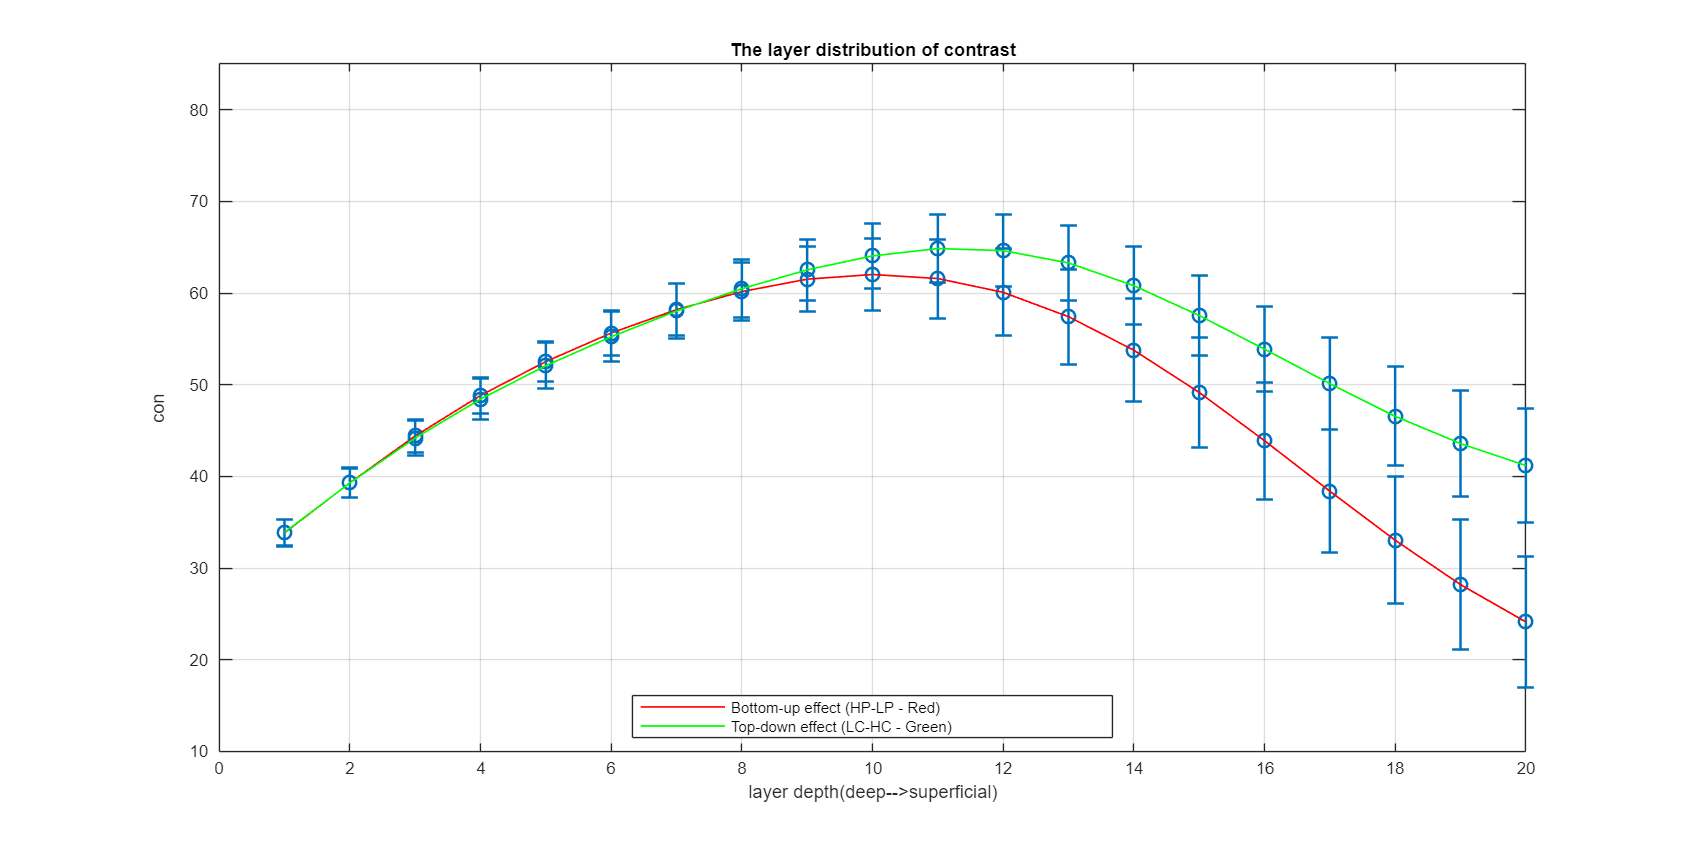


figure('Position',[100, 100, 2400, 1200]);

alldata_beta={bottomup_beta, topdown_beta};
% alldata_t={bottomup_t,topdown_t};
% for stattype=1:2
    for dataidx=1:2
        % Calculate column-wise mean and standard error
%         if stattype==1
            data=alldata_beta{dataidx};
%             titlenm='The layer distribution of contrast values';
            ylabltxt='beta';
%         elseif stattype==2
%             data=alldata_t{dataidx};
%             titlenm='The layer distribution of t stat';
%             ylabltxt='t-stat';
%         end
        titlenm='The layer distribution of contrast';
        ylabltxt='con';
        columnMeans = mean(data, 1); % Mean of each column
        columnStdErrors = std(data, 0, 1) ./ sqrt(size(data, 1)); % Standard error
%         subplot(1,2,stattype)
%         subplot(1,2,dataidx)
        % Create the scatter plot
%         legend('Bottom-up affect (main eff of pain - Red)','Top-down (main effect of cognition - Blue)', 'Location', 'south');

        errorbar(1:20, columnMeans, columnStdErrors, ...
            'o', 'LineWidth', 1.5, 'MarkerSize', 8, 'Color', [0 0.4470 0.7410], 'CapSize', 10);
        hold on;
        
        % Connect the points with a line
        if dataidx==1
            lineHandle1 = plot(1:20, columnMeans, '-r', 'LineWidth', 1);
        else
            lineHandle2 = plot(1:20, columnMeans, '-g', 'LineWidth', 1);
        end

        % Customize the plot
        xlabel('layer depth(deep-->superficial)');
        ylabel(ylabltxt);
        ylim([10 85])
%         ylim([-10 125])
        % Add legend only for the lines
        
    %     label()
        title(titlenm);
        grid on;
        
    end
    legend([lineHandle1, lineHandle2], ...
        {'Bottom-up effect (HP-LP - Red)', ...
        'Top-down effect (LC-HC - Green)'}, ...
        'Location', 'south');
    hold off;

% end

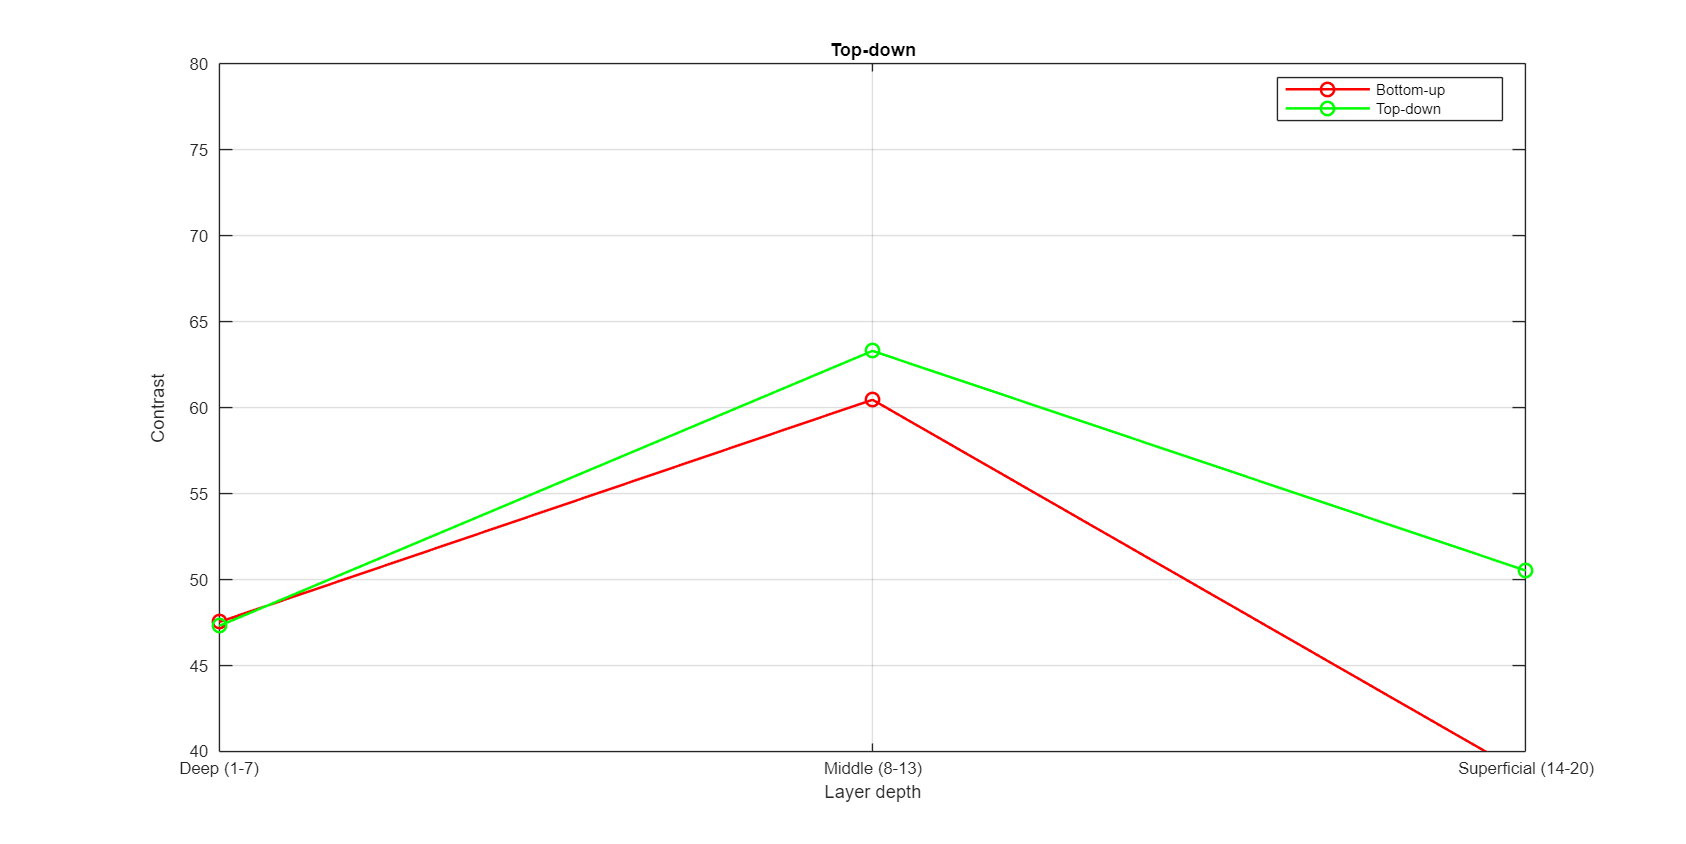

% Create a separate figure
figure('Position', [100, 100, 2400, 1200]);

% Define bin ranges
binRanges = {[1:7], [8:13], [14:20]};
binLabels = {'Deep (1-7)', 'Middle (8-13)', 'Superficial (14-20)'};

% Initialize data for binned means
binnedMeans = zeros(2, length(binRanges)); % Two rows for bottom-up and top-down
ploidx=0;
for dataidx = 1:2
    ploidx=ploidx+1;
    if dataidx == 1
        data = alldata_beta{dataidx};
        legendLabel = 'Bottom-up';
        lineColor = 'r';
    else
        data = alldata_beta{dataidx};
        legendLabel = 'Top-down';
        lineColor = 'g';
    end
%     subplot(1,2,ploidx)
    % Compute the means for each bin
    for binIdx = 1:length(binRanges)
        binCols = binRanges{binIdx}; % Get the column indices for the bin
        binnedMeans(dataidx, binIdx) = mean(mean(data(:, binCols), 1)); % Mean over bin
    end
    
    % Plot the binned means
    plot(1:length(binRanges), binnedMeans(dataidx, :), '-o', 'LineWidth', 1.5, ...
        'MarkerSize', 8, 'Color', lineColor, 'DisplayName', legendLabel);
    hold on

    xticks(1:length(binRanges));
    xticklabels(binLabels);
    xlabel('Layer depth');
    ylabel('Contrast');
    
    grid on;
    title(legendLabel);
    legend('Location', 'northeast');
    ylim([40 80])
end

% Customize the plot


hold off;

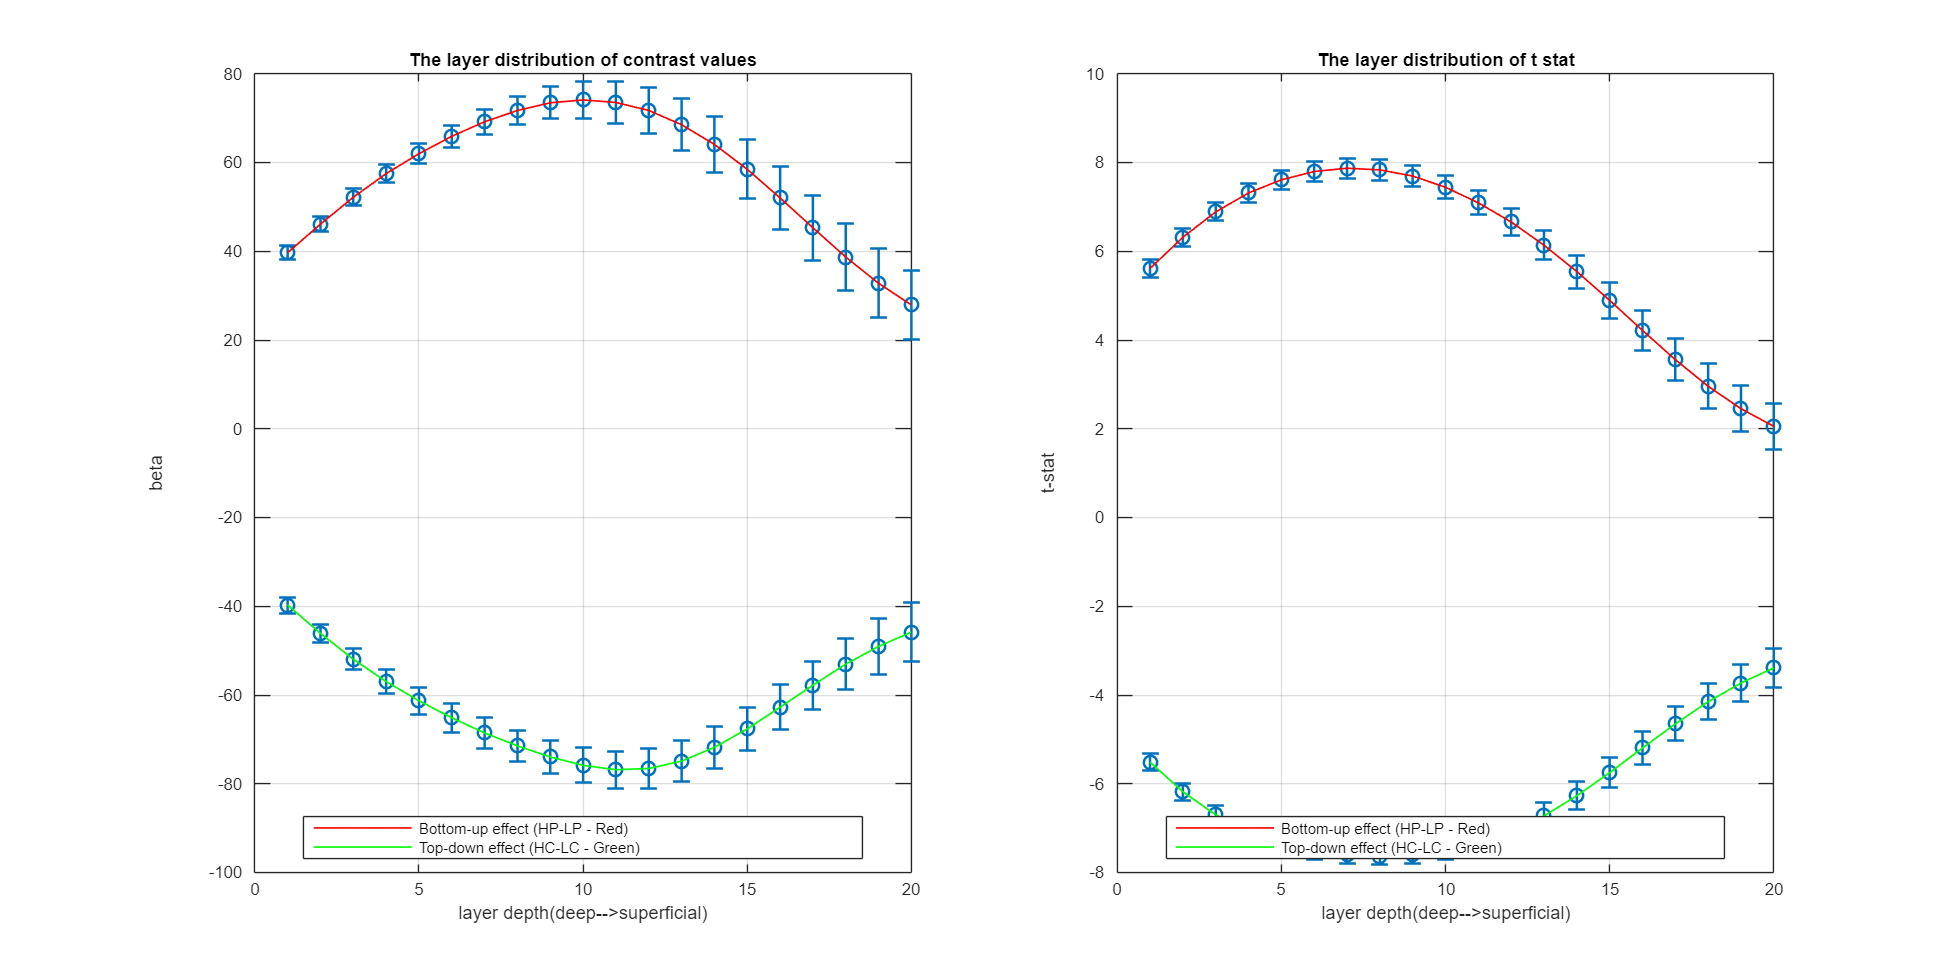



for subj=1:length(allsubjlayer)
    
    topdown_beta(subj,:)=allsubjlayer{subj}.beta(:,1,1);
    bottomup_beta(subj,:)=allsubjlayer{subj}.beta(:,1,2);
    
    topdown_t(subj,:)=allsubjlayer{subj}.T(:,1,1);
    bottomup_t(subj,:)=allsubjlayer{subj}.T(:,1,2);

%     HC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,1);
% 
%     LC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,2);
%     allsubjlayerresp(subj,:)=mean(squeeze(allsubjlayer{subj}.beta(:,:,:,1)),2)';    
end
figure('Position',[100, 100, 2400, 1200]);
alldata_beta={bottomup_beta, topdown_beta};
alldata_t={bottomup_t,topdown_t};
for stattype=1:2
    for dataidx=1:2
        % Calculate column-wise mean and standard error
        if stattype==1
            data=alldata_beta{dataidx};
            titlenm='The layer distribution of contrast values';
            ylabltxt='beta';
        elseif stattype==2
            data=alldata_t{dataidx};
            titlenm='The layer distribution of t stat';
            ylabltxt='t-stat';
        end
        columnMeans = mean(data, 1); % Mean of each column
        columnStdErrors = std(data, 0, 1) ./ sqrt(size(data, 1)); % Standard error
        subplot(1,2,stattype)
        % Create the scatter plot
%         legend('Bottom-up affect (main eff of pain - Red)','Top-down (main effect of cognition - Blue)', 'Location', 'south');

        errorbar(1:20, columnMeans, columnStdErrors, ...
            'o', 'LineWidth', 1.5, 'MarkerSize', 8, 'Color', [0 0.4470 0.7410], 'CapSize', 10);
        hold on;
        
        % Connect the points with a line
        if dataidx==1
            lineHandle1 = plot(1:20, columnMeans, '-r', 'LineWidth', 1);
        else
            lineHandle2 = plot(1:20, columnMeans, '-g', 'LineWidth', 1);
        end

        % Customize the plot
        xlabel('layer depth(deep-->superficial)');
        ylabel(ylabltxt);
        % Add legend only for the lines
        
    %     label()
        title(titlenm);
        grid on;
        
    end
    legend([lineHandle1, lineHandle2], ...
        {'Bottom-up effect (HP-LP - Red)', ...
        'Top-down effect (HC-LC - Green)'}, ...
        'Location', 'south');
    hold off;
end

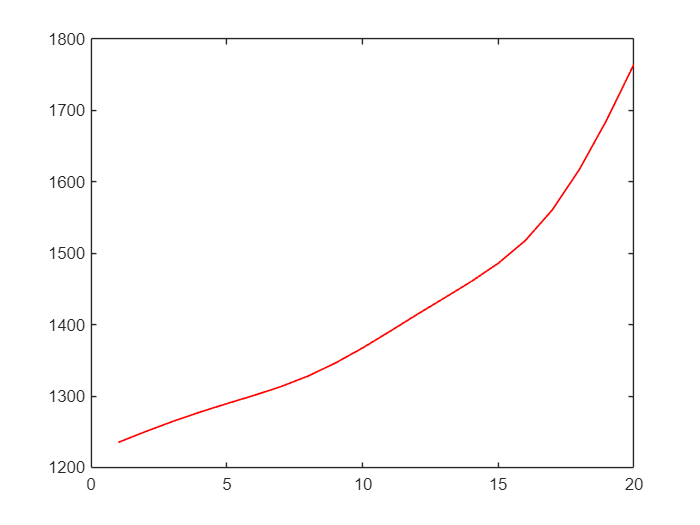

%check the bold response layerdependency
load('C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7402\functionalmasks\interimdata_rwls.mat')
figure;
vertexmean=squeeze(mean(interimdata_columns.layeractivation,1));
layermean=mean(vertexmean,2)';
plot(1:20, layermean, '-r', 'LineWidth', 1);